## Q1 - Linear Diffusion

Implement linear diffusion and analyze the input and result image (use as input Sun-girl image):

### Q1a - analyze

Compute and plot three graphs of the following measures as a function of time:

 i. Mean value of the image.

 ii. Standard deviation. 

%I = loadImageFromSubfolder('Ex1', 'sun_girl.png');
clear;close all;clc;
g = im2double(imread("Ex1/sun_girl.png")); %0-1 grayscale

%We assume model of: f=g*k+n
%t= 2; %how long we do the diffusion
%sigma=sqrt(2*t);
%ksize = 7;
noise_std = 0.1;
n = noise_std*randn(size(g));
%n = imgaussfilt(randn(size(g)), 1);

%k = fspecial('gaussian',ksize,sigma);
%f = imfilter(g,k,"symmetric","same","conv") + n;
f = g + n;
u0 = f; %initial guess\condition
iter = 200; %how many epochs
dt = 0.01; %time step - remember CFL
lambda=0.1; %how much weight to give fidelity term
[u, mean_vals, std_vals] = linearDiffusion(f,u0,iter,dt,lambda);



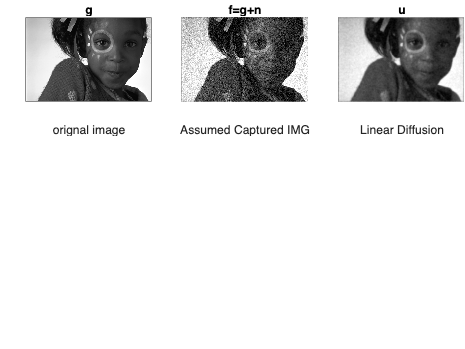

figure;
titles = {"g","f=g+n","u"};
t = tiledlayout(3,3,'Padding','tight','TileSpacing','compact');
nexttile;  imshow(g,'InitialMagnification',100); title(sprintf(titles{1})); xlabel("orignal image")
nexttile;  imshow(f,'InitialMagnification',100); title(sprintf(titles{2})); xlabel("Assumed Captured IMG")
nexttile;  imshow(u,'InitialMagnification',100); title(sprintf(titles{3})); xlabel("Linear Diffusion")

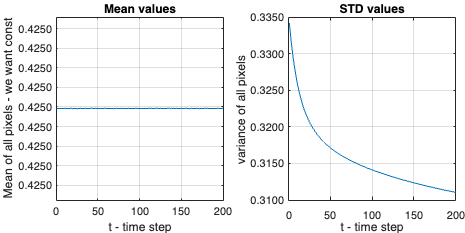


%[left,bottom,width,height]
figure('Position', [1, 1, 600, 300])
titles = {"Mean values","STD values"};
t = tiledlayout(1,2,'Padding','tight','TileSpacing','tight');
nexttile;  plot(mean_vals); title(sprintf(titles{1}));ytickformat("%.4f");grid on; xlabel("t - time step"); ylabel("Mean of all pixels - we want const");
nexttile;  plot(std_vals); title(sprintf(titles{2}));ytickformat("%.4f");grid on;xlabel("t - time step"); ylabel("variance of all pixels ")

**q. Explain the trends and why they occur.**

**Answer:**

When we perform perform diffusion, we mean that we gradually blend (or blur) the image with the noise or let pixels diffuse into the neighboring pixels.

The mean of an image, i.e. the mean of the pixel values, corresponds to the overall brightness of the image. If the mean changes, the image may become brighter or darker which is unwanted (because we want to improve the image quality and conserve it). This would force the model to correct brightness shifts in addition to denoising which adds additional unwanted complexity. By keeping the mean constant, we add a constraint for the overall intensity to remain stable, this simplifies the reconstruction, because the average color of the image stays the same.

The global standard deviation (STD) of pixel values corresponds to overall contrast in the image, if we assume that the image has white noise, some part of the std range will be related to the noise level, we can say that decreasing the std in the early stages, corresponds to removing\decreasing the noise, in return the image will become cleaner (but because we know that linear diffusion is equal to gaussian filtering, the noise will reduce but the image will be blurrier) , However if we continue to decrease too much, the pixel values will become too uniform, and we will get a washed out flat image (DC/over-smoothed).

**NOT SURE IF NEED TO WRITE ANYTHING ELSE**

### Q1b - compare

Compare diffusion to Gaussian convolution with equivalent sigma. If there is a difference, explain why.

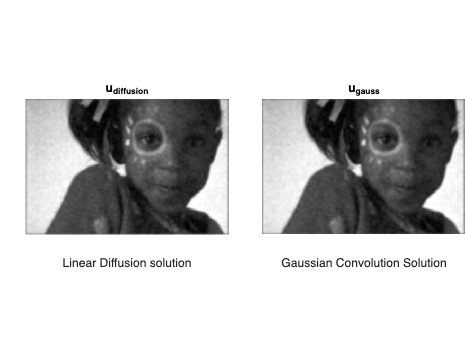

T = iter * dt;          % total diffusion time
sigma = sqrt(2*T);      
f_gauss = imgaussfilt(f, sigma,"Padding","symmetric");  % equivalent Gaussian smoothing
figure;
%imshowpair(u, f_gauss, 'montage');
%title('Left: Iterative Diffusion | Right: Gaussian Convolution');

%figure;
%C = imfuse(u,f_gauss,'falsecolor','Scaling','joint','ColorChannels',[1 2 0]);
%imshow(C);

%std of fguass:
%std(f_gauss(:)

figure;
titles = {"u_{diffusion}","u_{gauss}"};
t = tiledlayout(1,2,'Padding','tight','TileSpacing','compact');
nexttile;  imshow(u,'InitialMagnification',100); title(sprintf(titles{1})); xlabel("Linear Diffusion solution")
nexttile;  imshow(f_gauss,'InitialMagnification',100); title(sprintf(titles{2})); xlabel("Gaussian Convolution Solution")

**Answer:**

We proved analytically using PDE (q1 in hw), that the solution for linear diffusion is: $u\left(t,x\right)=f\left(x\right)*g_{\sigma \left(t\right)} \left(x\right)$, where $g_{\sigma \left(t\right)} \left(x\right)$ is a Gaussian kernel, and $\sigma \left(t\right)=\sqrt{2T}$.

So Linear Diffusion is mathematically equivalent to Gaussian Convolution, but diffusion is more flexible.

**NOT SURE WHAT TO WRITE HERE**

### Q1c - Inverse Diffusion

Blur an image without noise and with noise std=2. 

Perform linear inverse diffusion for a short time, compare the results.

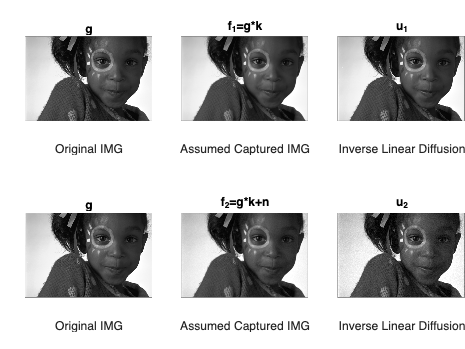

clear;close all;clc;
g = im2double(imread("Ex1/sun_girl.png"));
iter = 20;
dt = 0.01;
T = iter * dt;% diffusion time
lamda = 0.001;

sigma_blur = sqrt(2*T);    % sigma = sqrt(2*t) / kernel size
noise_std = 2/255; %Noise STD=2
f_clean = imgaussfilt(g, sigma_blur); u_clean = f_clean;
f_noisy = f_clean + noise_std*randn(size(g)); u_noisy = f_noisy;

[u,mean_vals,std_vals] = inverseLinearDiffusion(f_clean,u_clean,iter,dt,lamda);


figure;
titles = {"g","f_1=g*k","u_1"};
t = tiledlayout(2,3,'Padding','tight','TileSpacing','compact');
nexttile;  imshow(g,'InitialMagnification',100); title(sprintf(titles{1})); xlabel("Original IMG");
nexttile;  imshow(f_clean,'InitialMagnification',100); title(sprintf(titles{2}));xlabel("Assumed Captured IMG");
nexttile;  imshow(u,'InitialMagnification',100); title(sprintf(titles{3}));xlabel("Inverse Linear Diffusion");


[u,mean_vals,std_vals] = inverseLinearDiffusion(f_noisy,u_noisy,iter,dt,lamda);


titles = {"g","f_2=g*k+n","u_2"};
nexttile;  imshow(g,'InitialMagnification',100); title(sprintf(titles{1})); xlabel("Original IMG");
nexttile;  imshow(f_noisy,'InitialMagnification',100); title(sprintf(titles{2}));xlabel("Assumed Captured IMG");
nexttile;  imshow(u,'InitialMagnification',100); title(sprintf(titles{3}));xlabel("Inverse Linear Diffusion");

**Answer:**

We learnt that Inverse Diffusion occurs when the diffusion coefficient becomes negative:$u_t =-\triangle u$. 

This will cause the image to become sharper (we are going "back in time"), as anticipated even when doing only a few iterations, the image with slight noise $f_2$, became sharper but the noise itself became more accentuated (stronger). while the image without the noise $f_1$ only got clearer. Diffusion removes high frequencies (edges) and Inverse Diffusion amplified high frequencies (edges) and it cannot distinguish noise from edges so the noise is also amplified.

function [u,mean_vals,std_vals] = linearDiffusion(f,u,iter,dt,lamda)
mean_vals = zeros(1,iter);
std_vals = zeros(1,iter);

for i=1:iter
[ux,uy] = grad(u);
u_t = div(ux,uy);
fidelity_t = f-u;
u = u+dt.*(u_t+lamda*fidelity_t);
mean_vals(i)=mean(u(:));
std_vals(i)=std(u(:));
end
end


function [u,mean_vals,std_vals] = inverseLinearDiffusion(f,u,iter,dt,lamda)
mean_vals = zeros(1,iter);
std_vals = zeros(1,iter);

for i=1:iter
[ux,uy] = grad(u);
u_t = -div(ux,uy);
fidelity_t = f-u;
u = u+dt.*(u_t+lamda*fidelity_t);
mean_vals(i)=mean(u(:));
std_vals(i)=std(u(:));
end
end







%in images we assume h=1
function [fx,fy] = grad(V)
%forward difference gradient
fx = V(:,[2:end,end])-V;%select all rows, and shift cols +1 right, and duplicate last col again so we get direlhe boundry of 0
fy = V([2:end,end],:)-V;
end

function bd = div(Vx,Vy)
%backward difference divergence
fx = Vx - Vx(:,[1,1:end-1]); fx(:,1)=Vx(:,1); fx(:,end)=-Vx(:,end-1);
fy = Vy - Vy([1,1:end-1],:); fy(1,:)=Vy(1,:); fy(end,:)=-Vy(end-1,:);
bd = fx + fy;
end

